%Spectral Analysis using Fourier Transform in MATLAB
%Dataset File: https://in.mathworks.com/matlabcentral/fileexchange/47976-spectral-analysis-webinar-code-zip
%Note: Ignore the Warnings with 'Clear All'

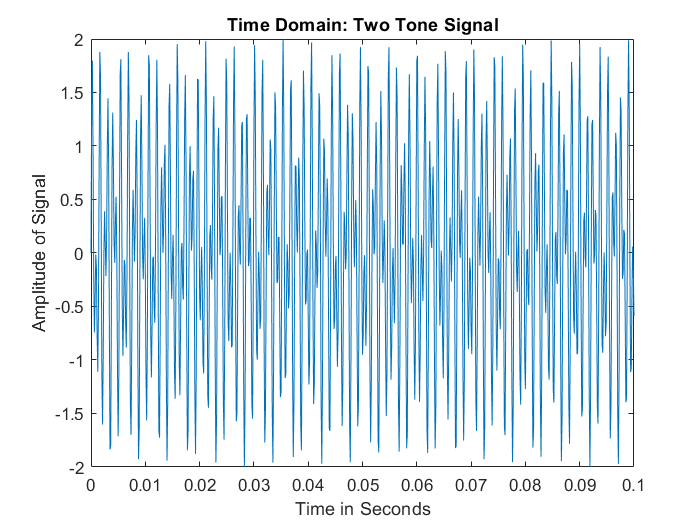

clc;
close all;
%FFT Constituents
%To start with: copy all the datasets and M files provided to the current
%folder or relocate to the folder containing these files
%Load Tone File
load two_tone.mat
%plot the Signal in Time Domain
plot (t,x);
title('Time Domain: Two Tone Signal')
ylabel('Amplitude of Signal')
xlabel('Time in Seconds')

%No easy way to figure out Frequency Components of the Signal

X=fft(x);
X(1:3)

ans =    1.2690 + 0.0000i   1.2691 - 0.0048i   1.2694 - 0.0096i


%Observation:: Input:Real Valued; Output: Complex Valued
%To interpret the complex number output, use abs() & angle() function
X_mag = abs(X)

X_mag =     1.2690    1.2691    1.2694    1.2699    1.2707    1.2716    1.2728    1.2742    1.2758    1.2777    1.2797    1.2820    1.2846    1.2873    1.2904    1.2936    1.2972    1.3010    1.3051    1.3095    1.3141    1.3191    1.3244    1.3301    1.3361    1.3424    1.3492    1.3563    1.3639    1.3719    1.3804    1.3894    1.3990    1.4091    1.4199    1.4313    1.4434    1.4562    1.4699    1.4845    1.5001    1.5167    1.5345    1.5535    1.5740    1.5960    1.6197    1.6453    1.6730    1.7031


X_phase = angle(X)

X_phase =          0   -0.0038   -0.0076   -0.0114   -0.0152   -0.0190   -0.0229   -0.0268   -0.0308   -0.0348   -0.0389   -0.0430   -0.0472   -0.0514   -0.0558   -0.0602   -0.0648   -0.0694   -0.0742   -0.0791   -0.0841   -0.0893   -0.0946   -0.1001   -0.1057   -0.1116   -0.1176   -0.1238   -0.1303   -0.1370   -0.1440   -0.1512   -0.1587   -0.1665   -0.1746   -0.1831   -0.1919   -0.2011   -0.2108   -0.2208   -0.2313   -0.2423   -0.2538   -0.2658   -0.2784   -0.2917   -0.3055   -0.3201   -0.3354   -0.3515


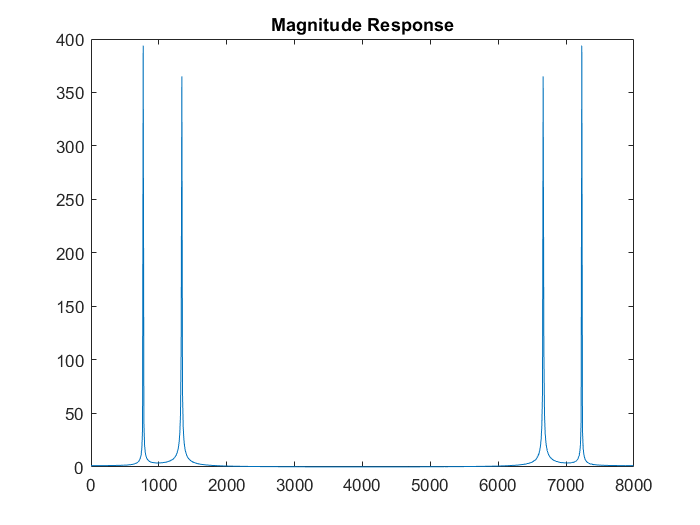

%Creating Frequency bins 
N= length (X);%Number of FFT points = length of the signal
%Creating Frequency Vector
Fbins = ((0:1/N:1-1/N)*Fs).';
%Magnitude Response Plot
plot (Fbins, X_mag )
title("Magnitude Response")

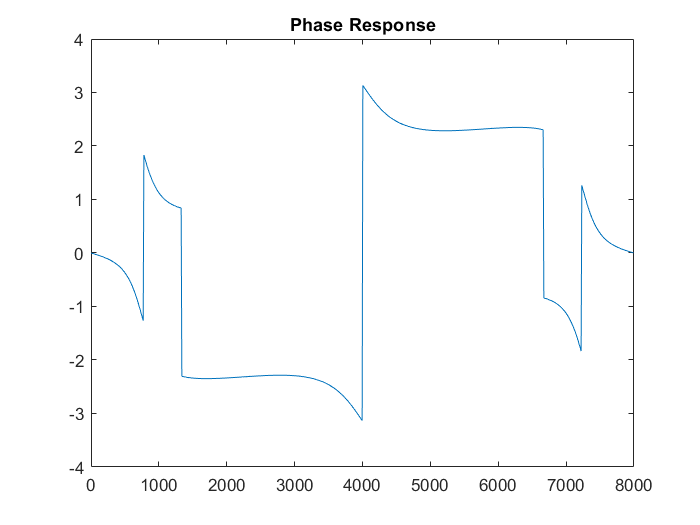

%4 peaks instead of 2 (Our original signal had 2 frequency composnents)
%Reason: FFT returns both +ve & -ve components
%Phase Response Plot 
plot(Fbins, X_phase) 
title('Phase Response')

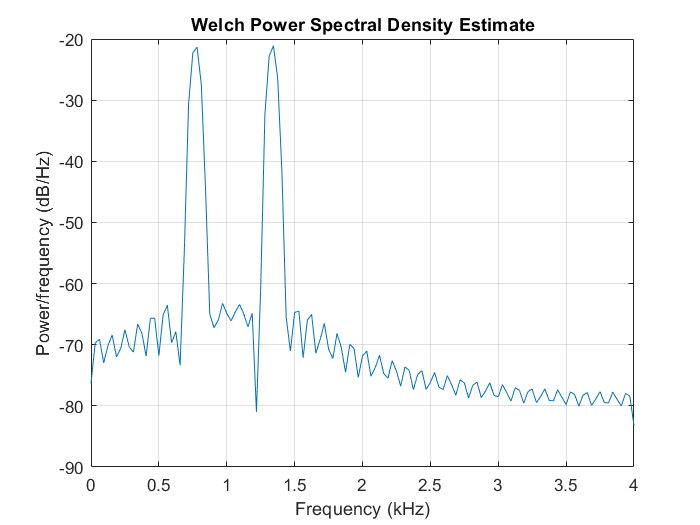

%pwelch Function for PSD
pwelch(x,[],[],[],Fs);

%no need to handle complex numbers, computing magnitude and phase info using different functions, sign of frwuency spectrum etc.
%All the challenges have been encountered.

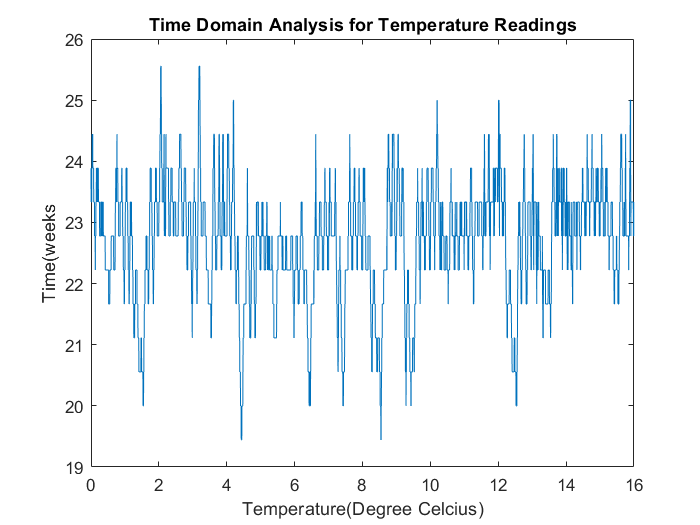

%Another example to explain how to check the periodicity of the signal
%Analysing Temperature Variations using pwelch
clc;
clear all;
close all;
load officetemp1.mat %16weeks 2 samples per hour.
plot (t, tempC);
title('Time Domain Analysis for Temperature Readings')
xlabel('Temperature(Degree Celcius)')
ylabel('Time(weeks')

%It is hard to tell if the data is periodic

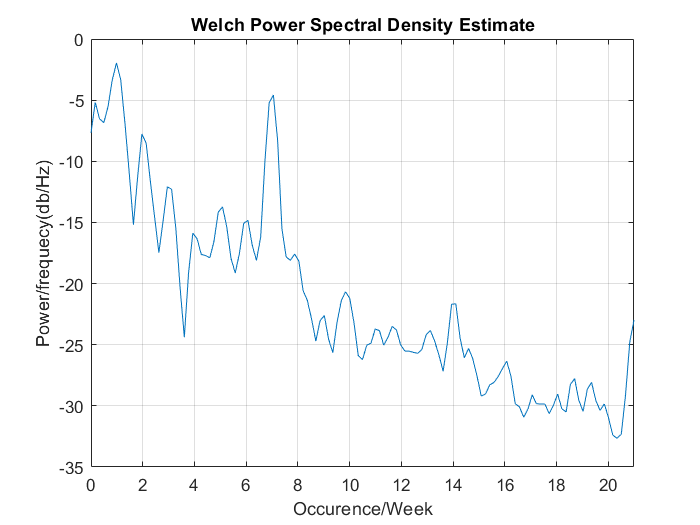

%Frequency Domain Analysis on Office Data
tempnorm = tempC - mean(tempC); %Focus on Fluctuations
fs=2*24*7;
pwelch(tempnorm,[],[],[], fs); 
xlim([0 21]); %Limiting the x-axis to view the weekly trend
xlabel("Occurence/Week");
ylabel("Power/frequecy(db/Hz)");

%observation: There are weekly high; and daily high 
%Reason: While working in office, temperatures are regulated
%During nights or during Weekends, temperatures are unregulated
%hence periodicity observed

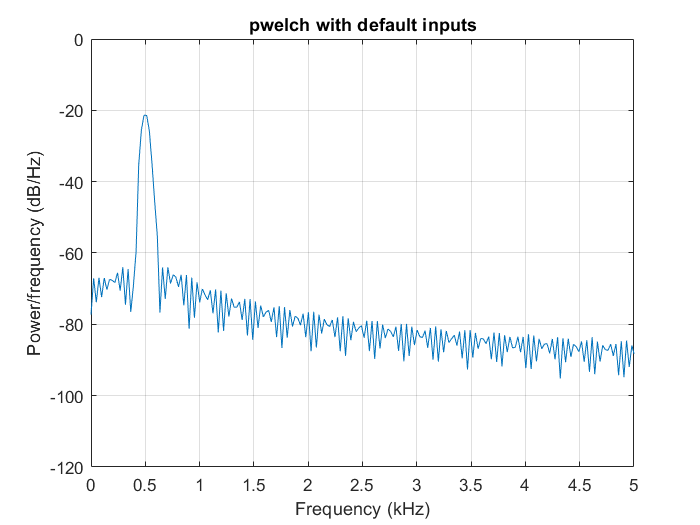

%more about pwelch
load ('winLen.mat')
pwelch(s,[],[],[],Fs);
%Fs=Sampling frequency
%N= Number of Samples
%f1=500Hz, f2=550Hz, Fs=50000, N=5000
%You may type 'f1', 'N' etc in the Editor Window to find out these
% variable values
title('pwelch with default inputs');
xlim([0 5]);
ylim([-120 0]);

%Expect: two peaks at f1 and f2.
%Observation: peak at 500 only
%Reason: 550 Hz unable to resolve
%due to length of current window (Haming Window in this case) is not wide
%enought to resolve the closely spaced frequency comp
%Longer the Window in time domain: Narrower in the frequency domain &
%better is the frequency resolution

Initializing Window Designer..

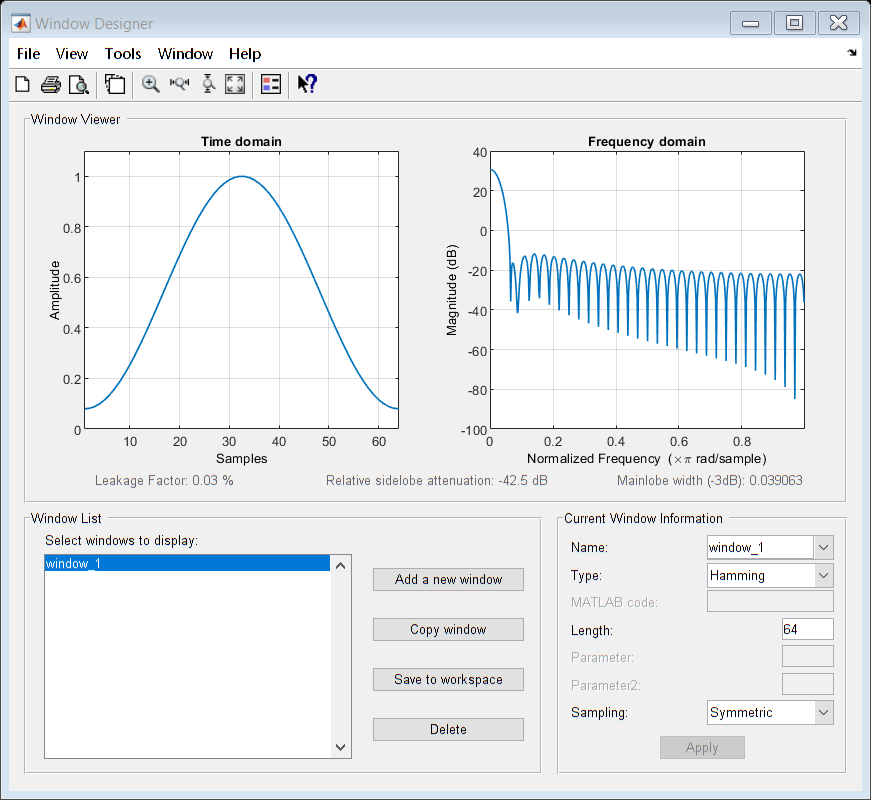

... done. 


% Hence we use 'Window Tool' to visualize this effect
windowDesigner %'wintool' previously

%we make three windows of size: 64,264.512
%As sample length increases in time domain, 
% the frequency reponse becomes narrower
%If the frequency comp of interest happen to lie withing the main lobe of
%interest, we won't be able to resolve them
%By increasing the window size, the comp gets narrower & we are able to
%resolve nearby frequency components

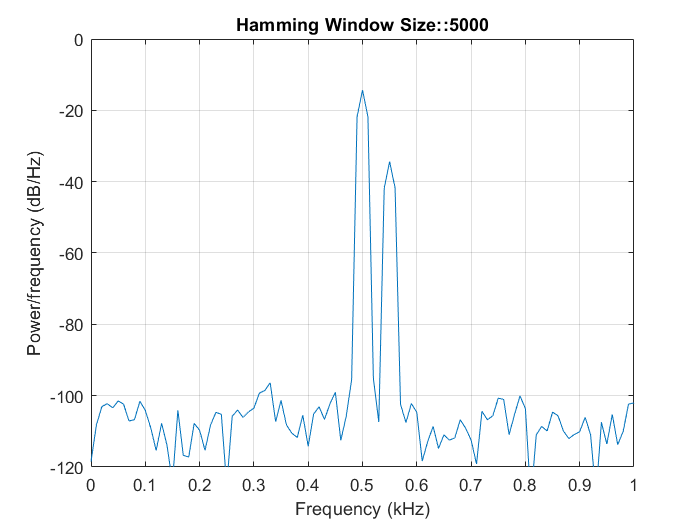

figure;
%###this window might not open in live editor; Use normal editor instead###
%Try the loop code in a normal editor, 'figure' window will definitely open there
for len = 500: 300: N 
pwelch(s, len, [], len, Fs);
title(sprintf('Hamming Window Size::%d', len));
ylim([-120 0]);
xlim([0 1]);
pause;
end 

%we can change the values until we reach to a window size where we are able
%to resolve the frequency components
%At about 4100, the two peaks are distinctly visible

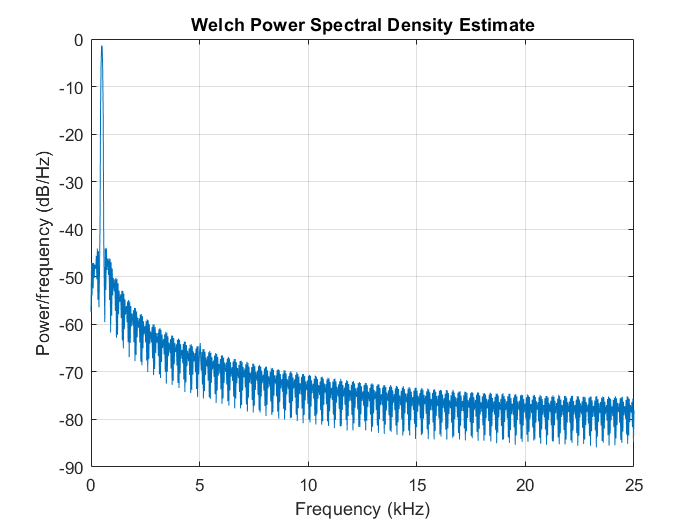

%another example of two vastly distanct frequencies
%unmasking the effect of sidelobes 
%Signals at 500Hz and 5Khz
%Fs=50000; N= 5000
load ('winType.mat');
%By Default
pwelch(s,[],[],[],Fs);

%Expect: 2 peaks at 500 & 5000Hz
%5KHz cannot be seen

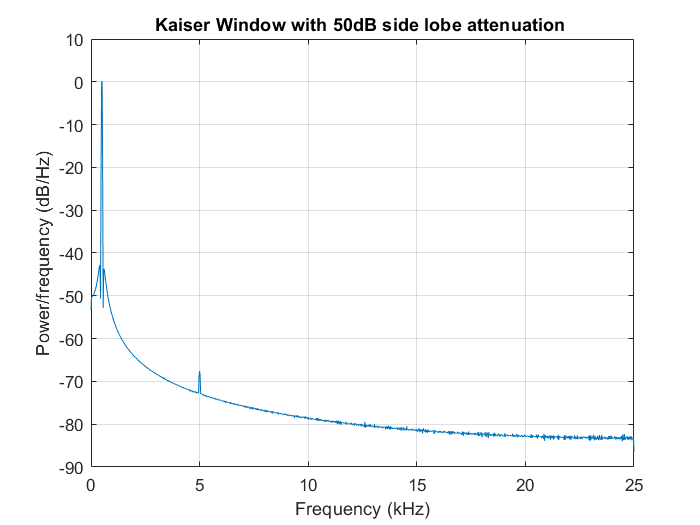

%Solution: Use Kaiser Window: gives the option of using a side lobe
%attenuation parameter (beta)
len=2050; %Window Size
h1= kaiser(len, 4.53); %50dB side lobe attenuation has beta = 4.53 (calculated using documentation)
%h1: vector of coef to be passed in pwelch
pwelch(s,h1,[],len,Fs);
%Kaiser helped 
title ('Kaiser Window with 50dB side lobe attenuation ')

%Observation: Kaiser Window has heped us in unmasking the 5KHz frequency

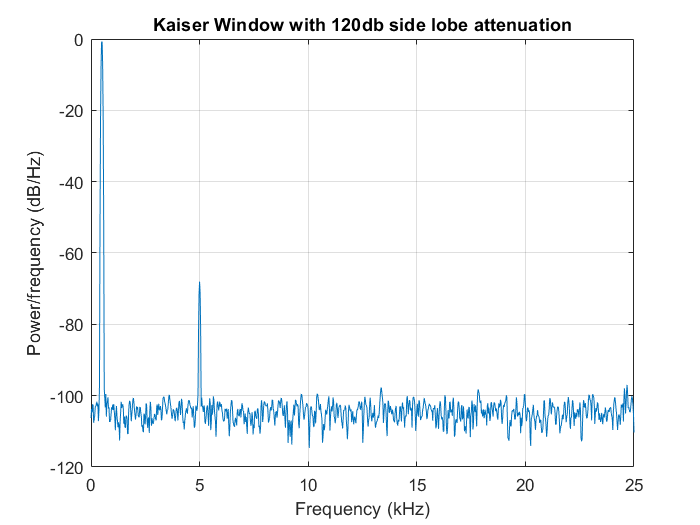

%We may increase the attenuation const to view changes 
h1= kaiser(len, 12.26); %120db Sidelobe attenuation 
pwelch(s,h1,[], len , Fs);
title('Kaiser Window with 120db side lobe attenuation');

%Even more significant Unmasking of 5KHz frequency comp

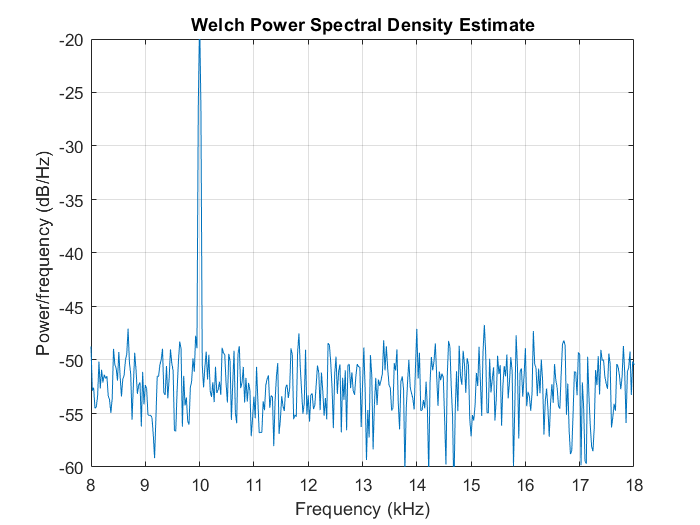

%The noise level was low & we were able to get the spectral detail
%There could be problems when a signal posseses problem of masking a
%particular tone due to high noise
clc;
close all;
clear all;
load winAvg.mat
%f1=10KHz & f2= 14kHz
%pwelch with Kaiser Window length 2050 & sidelobe 120dB
pwelch(s, kaiser(2050,4.23),[],2050,Fs);
xlim([8 18]);
ylim([-60 -20]);

%Observation: Amp @ 14KHz way higher than amp of 10Khz

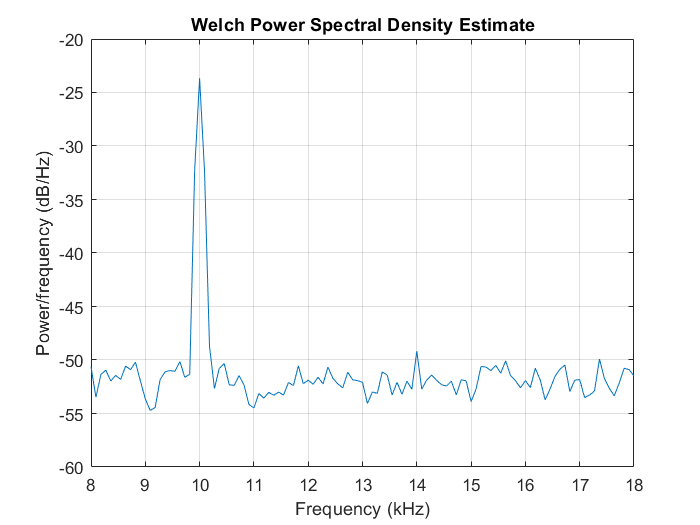

 %Sol: Avg more segments i.e., reduce window segment size
figure;
for len=2050:-100:550
pwelch(s, kaiser(len,4.23),[],len,Fs);
xlim([8 18]);
ylim([-60 -20]);
pause;
end

%observation: At some point we are able to have a peak for 14KHz too
%But the peak isn't sharp still due to averaging

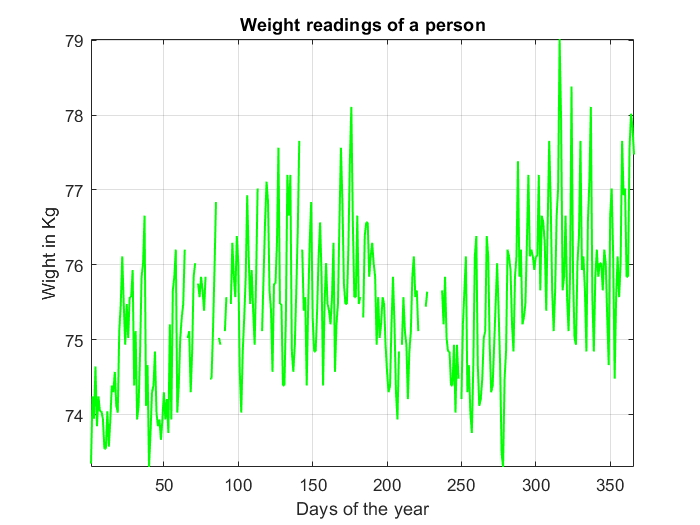

%So far, data used without any missing values
load weightdata.mat
plot(1:366, wgt, 'g', 'LineWidth', 1.2);
grid on;
axis tight;
ylabel('Wight in Kg');
xlabel('Days of the year')
title('Weight readings of a person');

fprintf('Missing %d samples of 366\n', sum(isnan(wgt)))

Missing 27 samples of 366


%passing a data that has missing values will result in error in pwelch

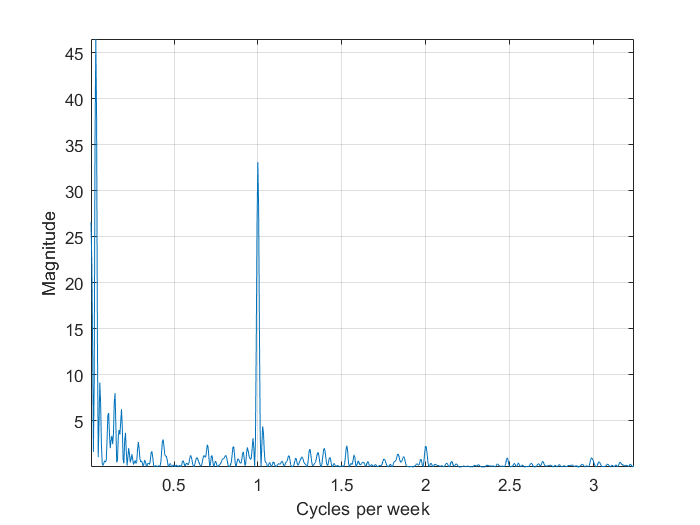

%Use Plomb function
[p,f] = plomb(wgt,7,"normalized");
%sampling frequency: 7 (7 samples per week)
plot(f,p)
xlabel('Cycles per week'); ylabel('Magnitude')
grid on; axis tight;

%Obs:two peaks occuring on the weekly cycle & on daily cycle
%Makes sense: Weekends are cheat days
%Daily pattern of variation of data

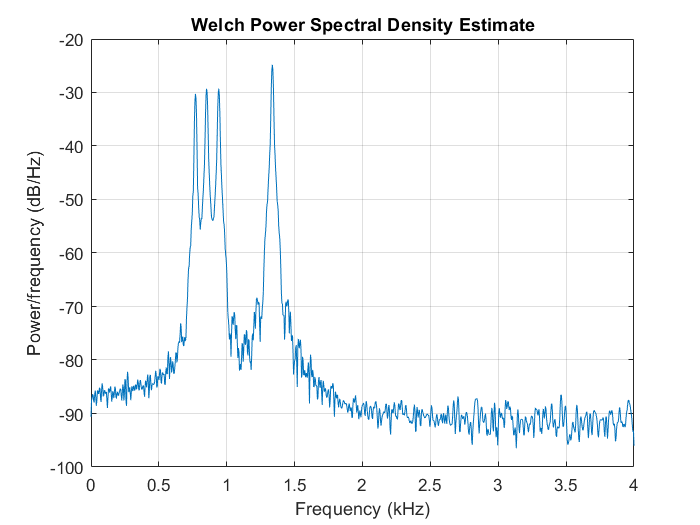

%Which button pressed on calling
clc;
close all;
clear all;
load dtmf.mat
%Frquency Domain
pwelch(x,[],[],[], Fs);

%Sampling Freuency=8kHz ; No of Samples:4800
%Each button generated 2 frequencies 
%Obs: Only 4 frequency comp are visible because 1 frequency is common to
%all the tone

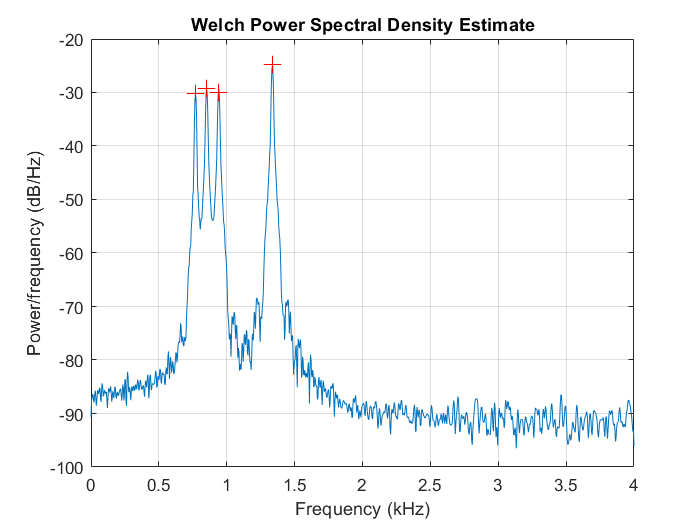

770 Hz, 852 Hz, 941 Hz and 1.336 KHz
770 Hz and 1.336 KHz -> 5 
852 Hz and 1.336 KHz -> 8 
941 Hz and 1.336 KHz -> 0 


%A file that contains the mapping of numbers with frquencies 
specDemoHelper1;

%Now we know which buttons were pressed but not sure of their order

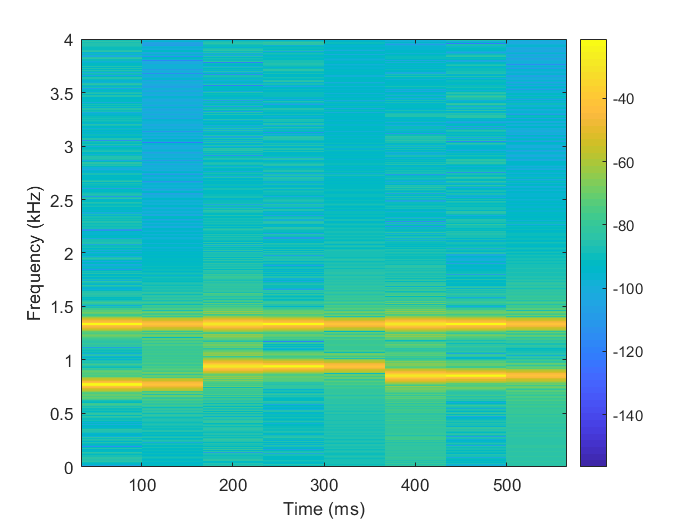

%Time-Frequency plot using spectrograms
spectrogram(x,[],[],[], Fs,'yaxis');
colorbar;

%Computes short time Fourier transform & returns frequency vs time 
%Colors represent Signal Power levels 
%default Window used is Hamming Window


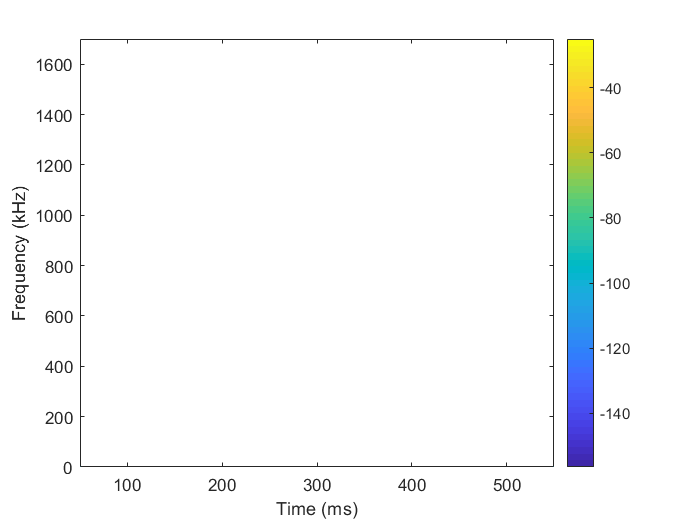

%Changing window length to obtain desired results 
segLen=[120 240 480 600 800 1000 1200 1600];
for itr = 1: numel(segLen)
    spectrogram(x,segLen(itr),[],segLen(itr),Fs,'yaxis')
    ylim([0 1700]);
    colorbar;
    pause;
end

%Dark blue bands indicate power levels and the time interval between
%successive key press
%short video size=Enough Time Resolution to measure silences duration
%for frequency resolution, obtain broad yellow band indicates Signal power
%spread across a band of frequencies 
%increasinf window size = resolution loss in time domain= better fre resol
%Find the best trade off between time and freq resoln

specDemoHelper2;

%To obtain the points at trade off
%Gives the order and the digits being pressed